## Generate ideal sensor values

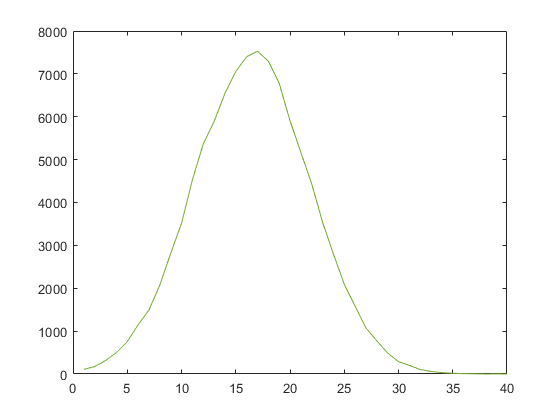

N=10e4;
d=floor([16*normrnd(0,1,[1 N])/3+16]);%, 16*normrnd(0,1,[1 N])/3+3*16]);
d(d>64) = [];
d(d<0) = [];
[a_orig,b] = hist(d,unique(d));
x = 1:size(a_orig,2);

figure
plot(x,a_orig,'Color',[0.4660 0.6740 0.1880]);
hold on

## Add defects

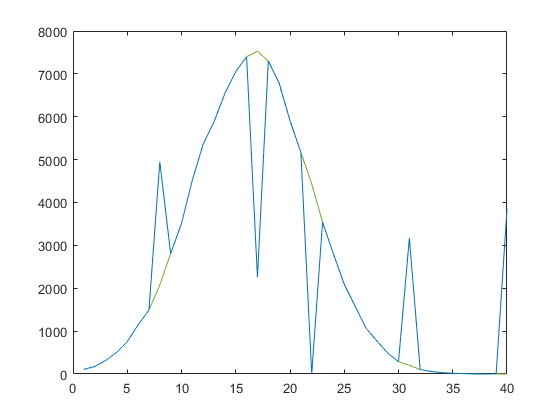

N_osh = 3;
osh = randi(size(a_orig,2),1,N_osh);
N_ush = 3;
ush = randi(size(a_orig,2),1,N_ush);

% osh = 18:25;
% ush = [];
maxa = max(a_orig);

a_defect = a_orig;
effective_defects = containers.Map('KeyType','double','ValueType','char');
for i = 1:size(osh,2)
%     strength = 1.5+.25*2*(rand-.5);
    strength = .5+.25*2*(rand-.5);
%     a_defect(osh(i)) = a_defect(osh(i))*strength;
    a_defect(osh(i)) = a_defect(osh(i)) + maxa*strength;
    effective_defects(osh(i)) = ['Overshoot'];%  ' num2str(round(100*(strength-1))) '%'];
end
for i = 1:size(ush,2)
    if not(isKey(effective_defects,ush(i)))
        strength = .5+.25*2*(rand-.5);
    %     a_defect(ush(i)) = a_defect(ush(i))*strength;
        a_defect(ush(i)) = max(a_defect(ush(i)) - maxa*strength,0);
        effective_defects(ush(i)) = ['Undershoot'];% ' num2str(round(100*(1-strength))) '%'];
    end
end

plot(x,a_defect,'Color',[0 0.4470 0.7410]);

## Detect defects

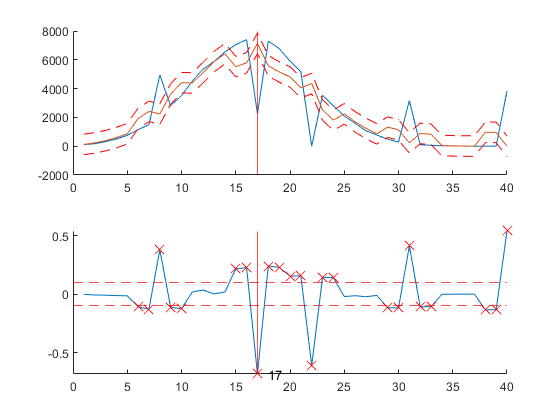

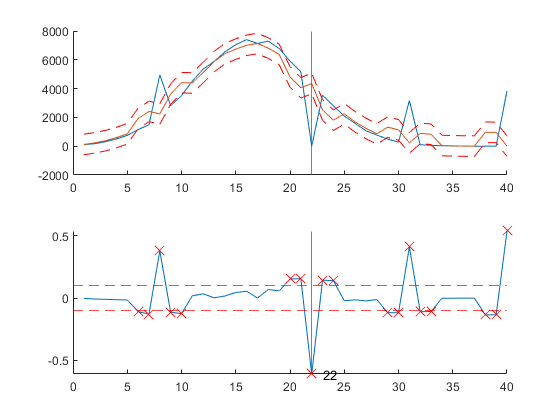

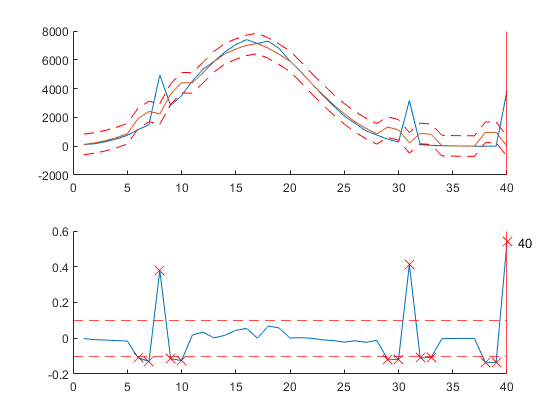

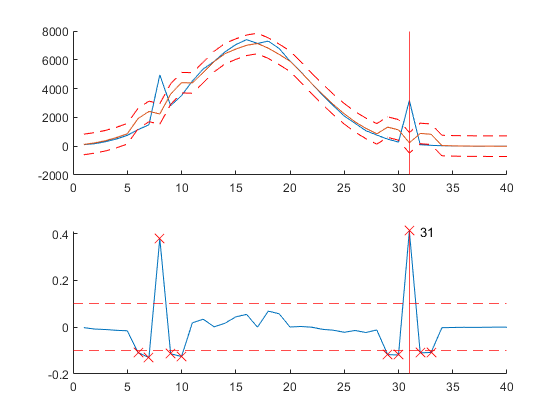

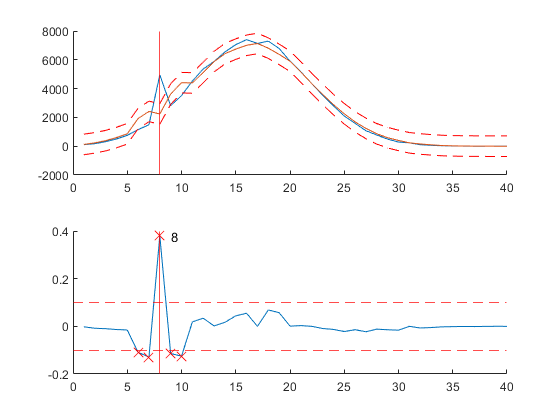

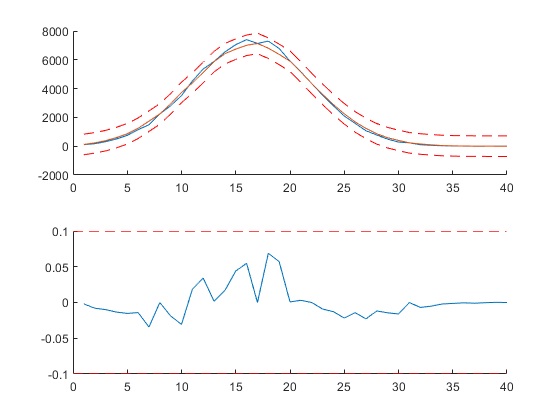

Reducing order to 1


Reducing tolerance to 6.02%


Done


defects = containers.Map('KeyType','double','ValueType','char');

% Order of the mean prediction
order = 2;
% Error tolerance
p = .1;
figs = [];

a = a_defect;

while 1

    ae = [zeros(1,order) a zeros(1,order)];
    xe = [x(1)-(1:order) x x(end)+(1:order)];

    % as = [];
    % as2 = [];
    am = [];

    for i = 1:size(x,2)
    %     as(i) = spline([xe(i-(1:order)+order) xe(i+(1:order)+order)], [ae(i-(1:order)+order) ae(i+(1:order)+order)], x(i));
    %     as2(i) = spline([xe(i) xe(i+2*order)], [ae(i) ae(i+2*order)], x(i));
        xl = i-(order:-1:1)+order;
        xr = i+(1:order)+order;
        yl = ae(xl);
        yr = ae(xr);
        am(i) = mean([yl yr]);
%         if order == 2
%             al = (yl(2) - yl(1))/(xl(2) - xl(1));
%             ar = (yr(2) - yr(1))/(xr(2) - xr(1));
%             if sign(al) ~= sign(ar)
%                 am(i) = spline([xl xr],[yl yr],i);
%             end
%         end
%         sl = norm(diff([xl' yl']));
%         sr = norm(diff([xr' yr']));
    end
    %am = smooth(a_defect,5,'sgolay',2)';
%     am = smooth(a_defect,0.1,'rlowess')';

    figs = [figs figure];
    subplot(2,1,1);
    hold on;
    plot(x,a);
    % plot(x,as);
    % plot(x,as2);
    plot(x,am);

    tam = max(am)*p;
%     tam = am*p;
    plot(x,am-tam,'r--');
    plot(x,am+tam,'r--');

%     das = abs(a-as);
%     das2 = abs(a-as2);
    dam = a-am;
    adam = abs(dam);
    
    rdam = dam/max(am);
%     rdam = dam./am;
    ardam = abs(rdam);

    subplot(2,1,2);
    hold on;
    % plot(x,das);
    % plot(x,das2);
    plot(x,rdam);
    yline(p,'r--');
    yline(-p,'r--');
    
    gtp = rdam>p;
    ltp = rdam<-p;
    xgtp = x(gtp);
    xltp = x(ltp);
    plot(xgtp,rdam(gtp),'rx','MarkerSize',10)
    plot(xltp,rdam(ltp),'rx','MarkerSize',10)

    [m,i] = max(ardam);

    if not(m>p) % the max we found is not outside tolerance
        order = order - 1;
        p = p/1.66;
        if order == 0
            disp('Done');
            break; % all the points are between the boundaries, no more defects
        else
            disp(['Reducing order to ' num2str(order)]);
            disp(['Reducing tolerance to ' num2str(round(100*p,2)) '%']);
            continue;
        end
    end
    
    xline(i,'r');
    text(i+1,rdam(i),num2str(i));
    subplot(2,1,1);
    xline(i,'r');

%     pause
    if not(isKey(defects,i))
        if sign(rdam(i)) > 0
            defects(i) = ['Overshoot'];%  ' num2str(round(100*adam(i)/am(i))) '%'];
        else
            defects(i) = ['Undershoot'];% ' num2str(round(100*adam(i)/am(i))) '%'];
        end
    end
    a(i) = am(i);

end

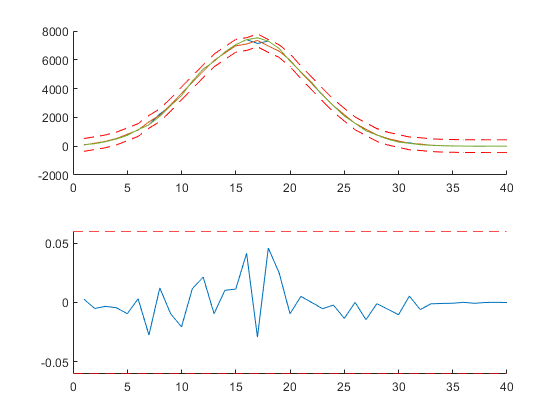


subplot(2,1,1);
plot(x,a_orig);


for i = size(figs,2):-1:1
    figure(figs(i));
end


effk = effective_defects.keys;
efftype = effective_defects.values;
k = defects.keys;
type = defects.values;


disp 'Effective defects:'

Effective defects:


disp([effk', efftype'])

    [ 8]    'Overshoot' 
    [17]    'Undershoot'
    [22]    'Undershoot'
    [31]    'Overshoot' 
    [37]    'Undershoot'
    [40]    'Overshoot' 




disp 'Anomalies detected on sensors:'

Anomalies detected on sensors:


disp([k', type'])

    [ 8]    'Overshoot' 
    [17]    'Undershoot'
    [22]    'Undershoot'
    [31]    'Overshoot' 
    [40]    'Overshoot' 



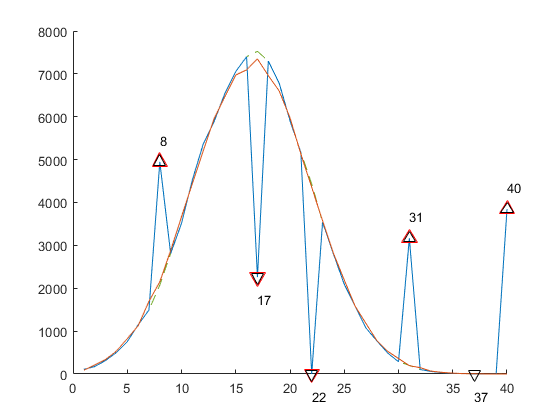


figure
hold on
plot(x,a_orig,'--','Color',[0.4660 0.6740 0.1880]);
plot(x,a_defect,'Color',[0 0.4470 0.7410]);
plot(x,am,'Color',[0.8500 0.3250 0.0980]);

for i = 1:size(k,2)
    marker = 'v';
    if strcmp(type{i},'Overshoot')
        marker = '^';
    end
    plot(k{i},a_defect(k{i}),['r' marker],'MarkerSize',10);
end

for i = 1:size(effk,2)
    marker = 'v';
    delta = -1;
    if strcmp(efftype{i},'Overshoot')
        marker = '^';
        delta = 1;
    end
    m = ylim; m = m(2);
    plot(effk{i},a_defect(effk{i}),['k' marker],'MarkerSize',8);
    text(effk{i},a_defect(effk{i})+delta*.065*m,num2str(effk{i}));
end